## Vehicular Platoons Coordination Simulator

This is the main file that one needs to execute to generate the results that we show in our paper.

clear all
close all
clc

% For different number of total vehicles, we may need to change the lower
% bound of the con0 in vehicle class for decentralization (0.001/0.0001)
% 0.007 0.005 0.004
rng(27)
% addpath(genpath('/home/shirantha27/mosek/10.2/toolbox/r2017aom'))
% addpath(genpath('/home/shirantha27/mosek/YALMIP-master'))


Creation of the network of platoons

%% Setup
network_index = 0;                     % network Index
numOfPlatoons = 1;                     % num of platoons
numOfVehicles = [12]; %[4,5,6,7,8,10];    % num of vehicles in each platoon, for N=8, 10, the lower bound of the con0 is set as 0.001
totalNumOfVehicles = sum(numOfVehicles);

%% Initial setup
vehicleSeperationMean = 10;
vehicleSeperationVar = 7; 
platoonSeperationMean = 10;
platoonSeperationVar = 2;

%% Define the initial vehicular position/velocity/acceleration 
vehiclePosition = 0;                % Zeroth vehicle position
vehicleVelocity = 0;                % Zeroth vehicle velocity
vehicleAcceleration = 0;            % Zeroth vehicle acceleration

state_ki = [vehiclePosition; vehicleVelocity; vehicleAcceleration];
desiredSeparation_ki = 0;              % Desired separation from the leader

%% Define the initial states and desired states for all the vehicles
for k = 1:1:numOfPlatoons           % for every platoon k
    
    parameters_k = [];
    noiseMean_k = [];
    noiseStd_k = [];
    states_k =  [];                       % initial states collection
    desiredSeperation_k = [];

    for i = 1:1:numOfVehicles(k)    % for every vehicle in the k-th platoon

        % Vehicle parameters (assumed homogenuous)
        mass_ki = 1500;
        length_ki = 2.5;
        Af_ki = 2.2;
        rho_ki = 0.78;
        Cd_ki = 0.35;
        Cr_ki = 0.067;
        tau_ki = 0.25;

        % Collection of the initial/initially desired states of each vehicle
        states_k = [states_k, state_ki];
        
        % Define the vehicle position/velocity/acceleration 
        vehiclePosition = vehiclePosition - (vehicleSeperationMean+length_ki) - vehicleSeperationVar*(rand(1)-0.5);
        vehicleVelocity = 0;
        vehicleAcceleration = 0;
        state_ki = [vehiclePosition; vehicleVelocity; vehicleAcceleration];
        

        % Desired vehicular positions 
        desiredSeperation_k = [desiredSeperation_k, desiredSeparation_ki];
        desiredSeparation_ki = desiredSeparation_ki + (vehicleSeperationMean+length_ki);

        % Collection of vehicle parameters
        vehicleParameters_i = [mass_ki; length_ki; Af_ki; rho_ki; Cd_ki; Cr_ki; tau_ki];
        parameters_k = [parameters_k, vehicleParameters_i];

        % Noise parameters
        % noisemean_ki = rand(3,1);
        % noisestd_ki = 0.1*rand(3,1);

        noisemean_ki = zeros(3,1);
        % rand(3,1)-0.5*ones(3,1);
        % noisestd_ki = 0.1*rand(3,1);
        noisestd_ki = 0.2*rand(3,1);

        noiseMean_k = [noiseMean_k, noisemean_ki];
        noiseStd_k = [noiseStd_k, noisestd_ki];
            
    end
    
    vehiclePosition = states_k(1,end) - platoonSeperationMean - platoonSeperationVar*(rand(1)-0.5);
    
    state_ki = [vehiclePosition; vehicleVelocity; vehicleAcceleration];
    desiredSeparation_ki = 0;

    parameters{k} = parameters_k;
    states{k} = states_k;
    desiredSeparation{k} = desiredSeperation_k;
    noiseMean{k} = noiseMean_k;
    noiseStd{k} = noiseStd_k;
      
end

net0 = Network(network_index,numOfPlatoons,numOfVehicles,parameters,states,desiredSeparation,noiseMean,noiseStd);

Plotting the network of platoons

disp(['Initial Platoon:'])

Initial Platoon:


fig1 = figure;
ax1 = gca;                   % gca = get current axis handle

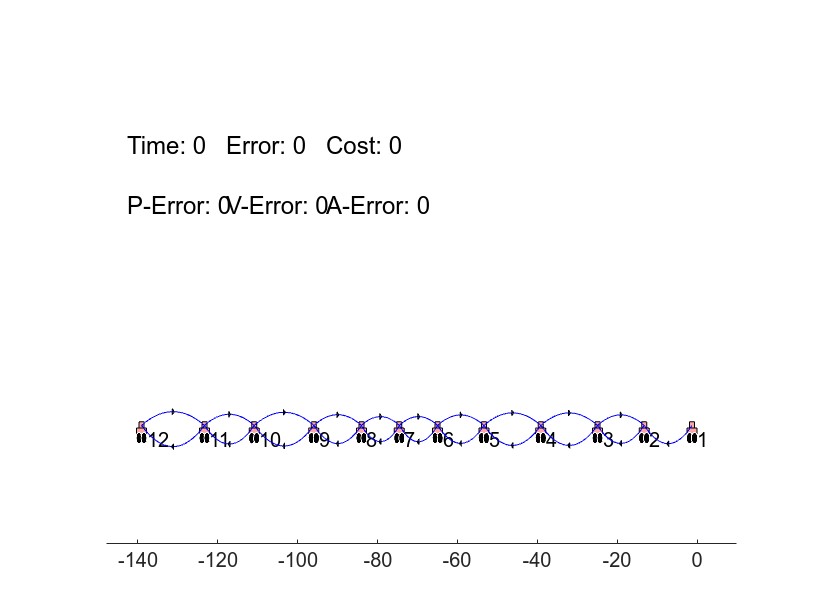

ax1.YAxis.Visible = 'off';   % hide out the y-axis from the plot
net0.drawNetwork(fig1)

Removing two vehicles and plotting the result

net1 = net0.copy();
net1.removeVehicles(1,[4,9],0); %errorDynamicsType argument left zero
% net1.removeVehicles(1,[],0); %errorDynamicsType argument left zero

disp(['Platoon after removing Vehicle 4 and Vehicle 7:'])

Platoon after removing Vehicle 4 and Vehicle 7:


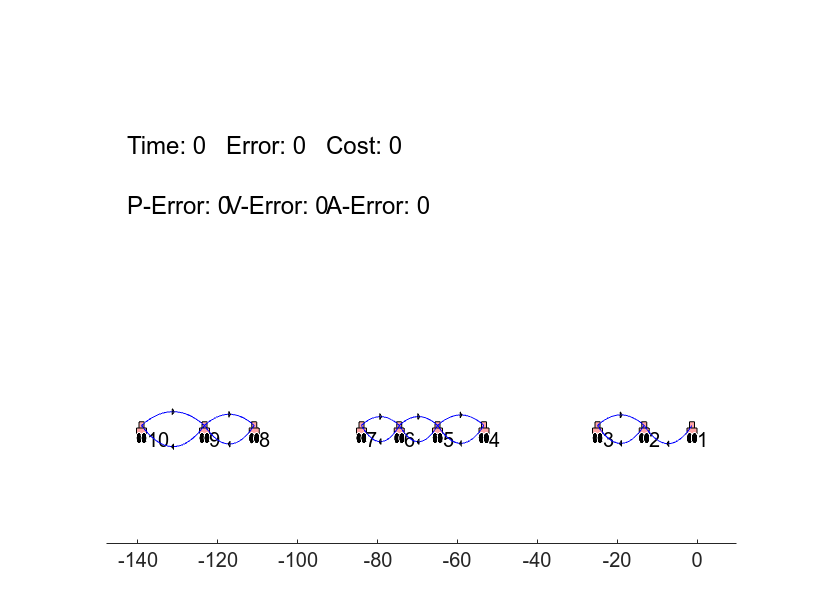

% Platoon simulation video figure setup
fig2 = figure;
ax2 = gca;                   % gca = get current axis handle
ax2.YAxis.Visible = 'off';   % hide out the y-axis from the plot
net1.drawNetwork(fig2)

#### Synthesizing controllers for the platoon

We will limit to error dynamics type 2, In this case, we will not use DSS constraints as well. We also fix pVals parameters. 

Common settings across all experiment configurations:

errorDynamicsType = 2;  % Error dynamics formulation 1 or 2
isDSS = 0;               % Involve DSS constraints (1) or not (0)

gammaSqBar = 10;        % For the constraint: gamma^2 <= gammaSqBar % Desired max noise attenuation
%%% Local passivating controller synthesis specifications 
% LowerBound on \nu and upperBound on \rho 
nuBar = -40;       % For the constraint: nuBar <= nu       
rhoBar = 15;       % For the constraint: rhoHat <= rho <= rhoBar

%%% Parameterized approach to co-design
%% Optimizing gammaSq with respect to the co-design parameters
% pVals = net1.optimizeCodesignParameters(isCentralized,isDSS)

%% An alternative: Trying some fixed set of parameters.
pVals = 0.15*ones(numOfPlatoons,max(numOfVehicles));

showPlots = 0;

**Configuration 1:** Centralized Stabilizing Control 

net1CS = net1.copy();

isCentralized = 1;      % Centralized or decentralized controller synthesis
isOnlyStabilizing = 1;  % Stabilizing controller or Disturbance robust Controller)

tic
status = net1CS.loadPlatoonControllers(errorDynamicsType,isCentralized,isDSS,isOnlyStabilizing,gammaSqBar,nuBar,rhoBar,pVals)

obj =   Platoon with properties:

     platoonIndex: 1
    numOfVehicles: 10
         vehicles: [1×10 Vehicle]
         topology: [1×1 Topology]
        graphics1: []
        graphics2: []
                K: {9×9 cell}
                R: []
        KSequence: []


status = logical
   1


toc

Elapsed time is 3.099724 seconds.



disp(['Platoon after synthesizing the topology (Centralized Stabilizing):'])

Platoon after synthesizing the topology (Centralized Stabilizing):


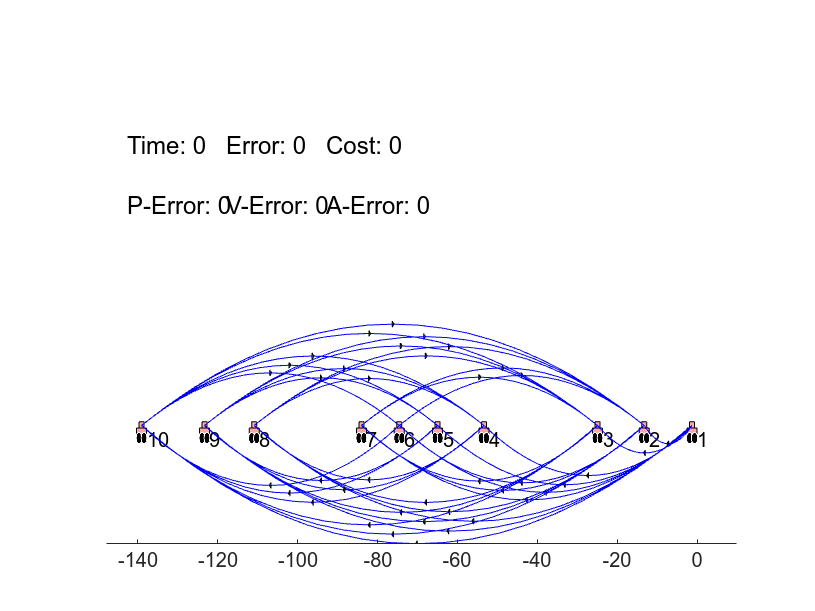

%%% Graphing the Resulting topology
fig3CS = figure;
ax3CS = gca;                   % gca = get current axis handle
ax3CS.YAxis.Visible = 'off';   % hide out the y-axis from the plot
net1CS.drawNetwork(fig3CS)

net1CSC = net1CS.copy();

[comCost,robCost]  = net1CS.evaluateTopology(showPlots)

comCost = 1.4738e-04

robCost = 51.3113

**Configuration 2:** Decentralized Stabilizing Control 

net1DS = net1.copy();

isCentralized = 0;      % Centralized or decentralized controller synthesis
isOnlyStabilizing = 1;  % Stabilizing controller or Disturbance robust Controller)

tic
status = net1DS.loadPlatoonControllers(errorDynamicsType,isCentralized,isDSS,isOnlyStabilizing,gammaSqBar,nuBar,rhoBar,pVals)

Global Synthesis Success


status = 1

toc

Elapsed time is 1.814852 seconds.



disp(['Platoon after synthesizing the topology (Decentralized Stabilizing):'])

Platoon after synthesizing the topology (Decentralized Stabilizing):


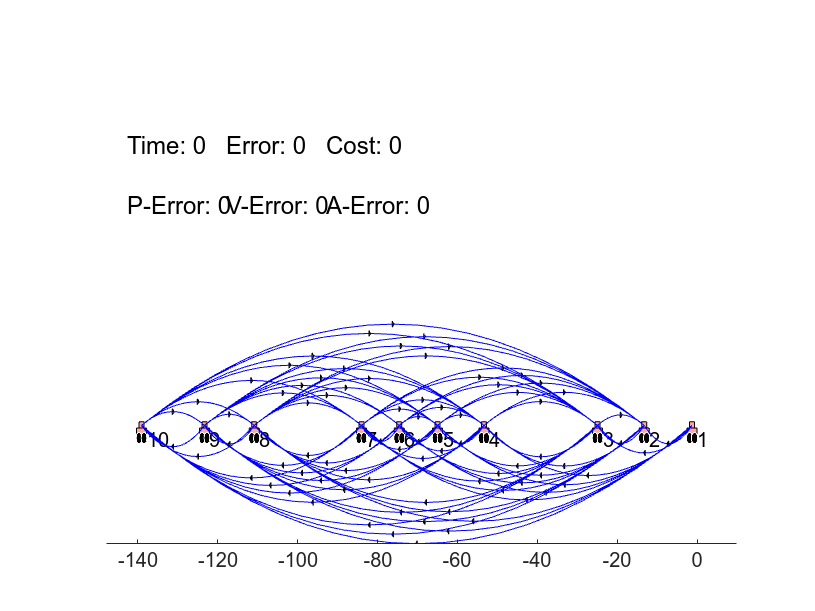

%%% Graphing the Resulting topology
fig3DS = figure;
ax3DS = gca;                   % gca = get current axis handle
ax3DS.YAxis.Visible = 'off';   % hide out the y-axis from the plot
net1DS.drawNetwork(fig3DS)

net1DSC = net1DS.copy();

[comCost,robCost]  = net1DS.evaluateTopology(showPlots)

comCost = 0.0038

robCost = 51.3240

**Configuration 3:** Centralized Robust Control 

net1CR = net1.copy();

isCentralized = 1;      % Centralized or decentralized controller synthesis
isOnlyStabilizing = 0;  % Stabilizing controller or Disturbance robust Controller)

% pVals = net1CR.optimizeCodesignParameters(isCentralized,isDSS)
% 0.0073	0.0093	0.0207	0.0071	0.0110	0.0065	0.0207	0.0075	0.0207

tic
[status, gammaSqVal, timeVal] = net1CR.loadPlatoonControllers(errorDynamicsType,isCentralized,isDSS,isOnlyStabilizing,gammaSqBar,nuBar,rhoBar,pVals)

status = logical
   1


gammaSqVal = 3.0366

timeVal = 0.9855

toc

Elapsed time is 1.003639 seconds.



disp(['Platoon after synthesizing the topology (Centralized Robust):'])

Platoon after synthesizing the topology (Centralized Robust):


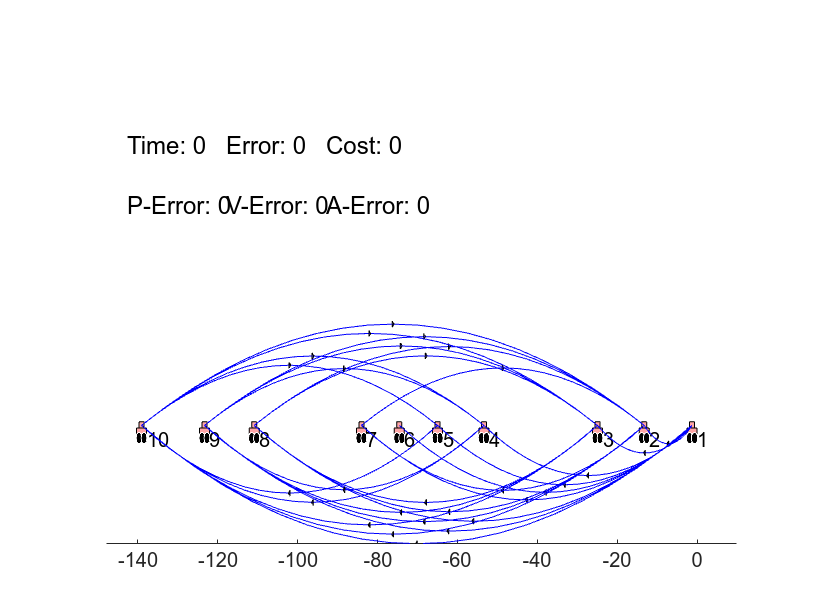

%%% Graphing the Resulting topology
fig3CR = figure;
ax3CR = gca;                   % gca = get current axis handle
ax3CR.YAxis.Visible = 'off';   % hide out the y-axis from the plot
net1CR.drawNetwork(fig3CR)

net1CRC = net1CR.copy();


[comCost,robCost]  = net1CR.evaluateTopology(showPlots)

comCost = 6.8565e-05

robCost = 51.3202

**Configuration 4:** Decentralized Robust Control 

net1DR = net1.copy();

isCentralized = 0;      % Centralized or decentralized controller synthesis
isOnlyStabilizing = 0;  % Stabilizing controller or Disturbance robust Controller)

% pVals = net1DR.optimizeCodesignParameters(isCentralized,isDSS)

tic
[status, gammaSqVal, timeVals] = net1DR.loadPlatoonControllers(errorDynamicsType,isCentralized,isDSS,isOnlyStabilizing,gammaSqBar,nuBar,rhoBar,pVals)

status = 1

gammaSqVal = 3.7735

timeVals =     0.5539    0.1916    0.1449    0.1572    0.2318    0.1731    0.3845    0.4283    0.2890


toc

Elapsed time is 0.704775 seconds.



disp(['Platoon after synthesizing the topology (Decentralized Robust):'])

Platoon after synthesizing the topology (Decentralized Robust):


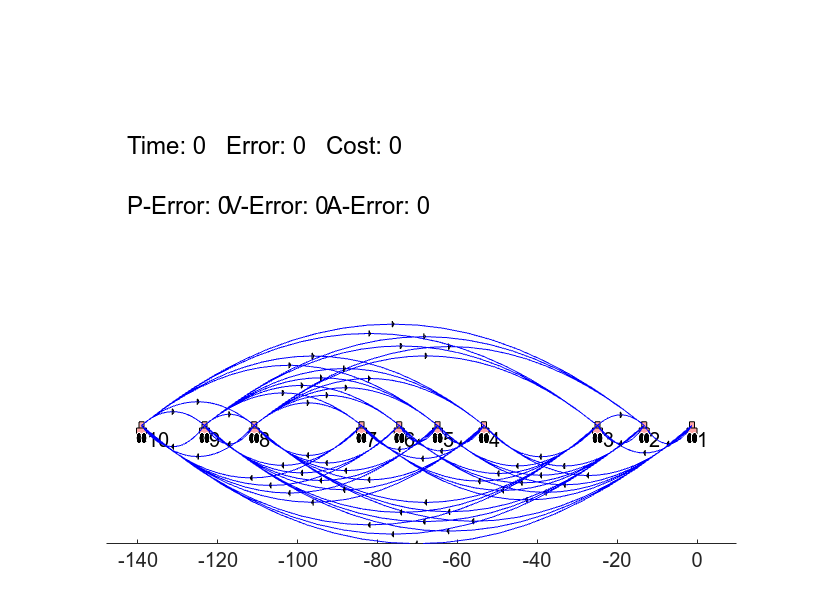

%%% Graphing the Resulting topology
fig3DR = figure;
ax3DR = gca;                   % gca = get current axis handle
ax3DR.YAxis.Visible = 'off';   % hide out the y-axis from the plot
net1DR.drawNetwork(fig3DR)

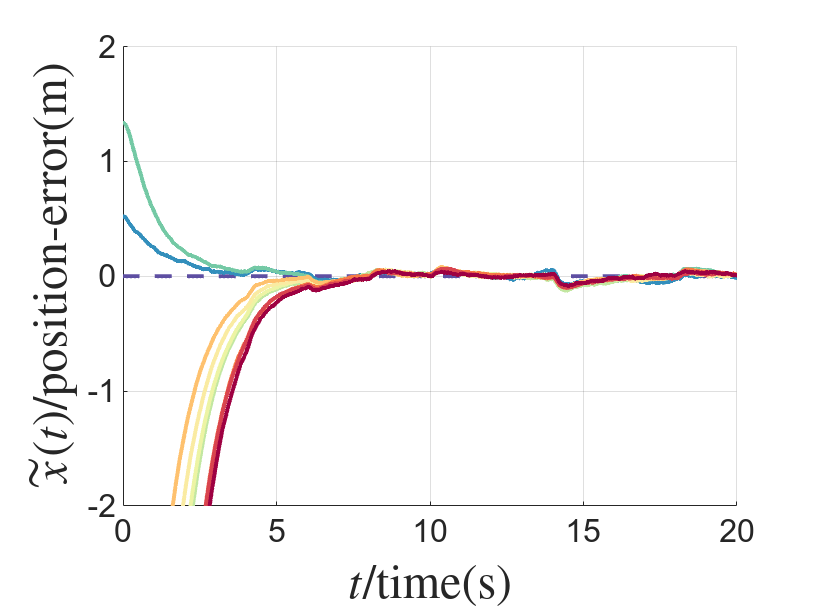

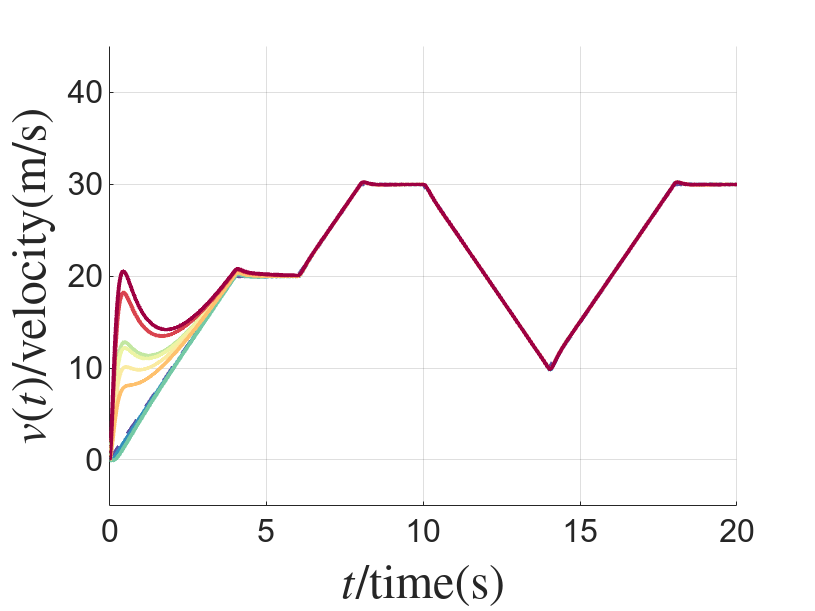

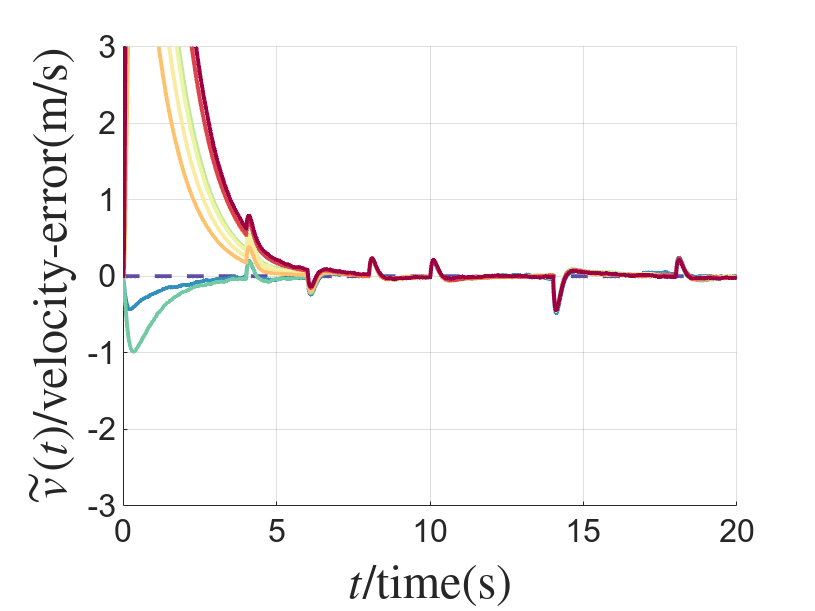

comCost = 0.0087

robCost = 51.3312

net1DRC = net1DR.copy();
net2 = net1DR.copy();

showPlots = 1;
[comCost,robCost]  = net1DR.evaluateTopology(showPlots)

Decentralized DSS

net1DDSS = net1.copy();

isDSS = 1;
isCentralized = 0;      % Centralized or decentralized controller synthesis
isOnlyStabilizing = 0;  % Stabilizing controller or Disturbance robust Controller)

% pVals = net1DR.optimizeCodesignParameters(isCentralized,isDSS)

tic
[status, gammaSqVal, timeVals] = net1DDSS.loadPlatoonControllers(errorDynamicsType,isCentralized,isDSS,isOnlyStabilizing,gammaSqBar,nuBar,rhoBar,pVals)

obj =   Platoon with properties:

     platoonIndex: 1
    numOfVehicles: 10
         vehicles: [1×10 Vehicle]
         topology: [1×1 Topology]
        graphics1: []
        graphics2: []
                K: {9×9 cell}
                R: []
        KSequence: {{1×1 cell}  {2×2 cell}  {3×3 cell}  {4×4 cell}  {5×5 cell}  {6×6 cell}  {7×7 cell}  {8×8 cell}  {9×9 cell}}


status = 1

gammaSqVal = 4.5767

timeVals =     0.1681    0.1874    0.2355    0.2680    0.3339    0.4206    0.3755    0.5105    0.4664


toc

Elapsed time is 0.492789 seconds.



disp(['Platoon after synthesizing the topology (Decentralized Robust DSS):'])

Platoon after synthesizing the topology (Decentralized Robust DSS):


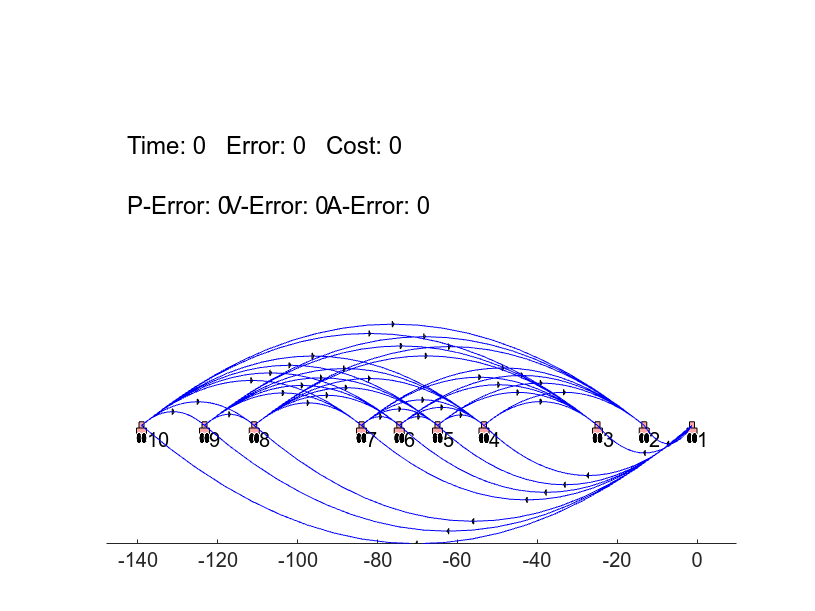

%%% Graphing the Resulting topology
fig3DDSS = figure;
ax3DDSS = gca;                   % gca = get current axis handle
ax3DDSS.YAxis.Visible = 'off';   % hide out the y-axis from the plot
net1DDSS.drawNetwork(fig3DDSS)

net1DDSSC = net1DDSS.copy();

showPlots = 0;
[comCost,robCost]  = net1DDSS.evaluateTopology(showPlots)

comCost = 0.0266

robCost = 51.3183

**Additional Compositionality Tests**

%%% To check compositionality, lets see K_{13} value at decentralized iteration = 3,4,5 and 6
% format long
net1DRC.platoons(1).KSequence
if ~isCentralized
    net1DRC.platoons(1).KSequence{3}{1,3}
    net1DRC.platoons(1).KSequence{4}{1,3}
    net1DRC.platoons(1).KSequence{5}{1,3}
    net1DRC.platoons(1).KSequence{6}{1,3}

    %%% Plotting intermediate topologies
    N = net1DRC.platoons(1).numOfVehicles;
    for i = 1:N-1
        i
        net1_i = net1DRC.copy();
        net1_i.removeVehicles(1,[(i+3):N],errorDynamicsType);
        disp(['Platoon with only ',num2str(i+2),' vehicles:'])
        fig4{i} = figure; 
        ax4{i} = gca;                   % gca = get current axis handle
        ax4{i}.YAxis.Visible = 'off';   % hide out the y-axis from the plot
        net1_i.drawNetwork(fig4{i})
    end
end





%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Compute the cost \sum_{i=1}^N cij*|K_ij|+c0*gamma

%Then we use hard constraint

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%%% In decentralized implementation, there are two things to consider:
% gammaSq_i needs to be costrainted at each subsystem i (or penalized considerably), 
% otherwise it tends to grow with i. Recall that max(gammaSq_i) = gammaSq. 
% There is a zero eigenvalue in the main LMI constraint (this is also in the
% centralized problem). This may be the reason why solver gives "Unknown Status" error.


%%% To further check compositionality, lets remove a vehicle
net1CSC.removeVehicles(1,[7,5,3],errorDynamicsType);
[comCost,robCost]  = net1CSC.evaluateTopology(showPlots)
net1DSC.removeVehicles(1,[7,5,3],errorDynamicsType);
[comCost,robCost]  = net1DSC.evaluateTopology(showPlots)
net1CRC.removeVehicles(1,[7,5,3],errorDynamicsType);
[comCost,robCost]  = net1CRC.evaluateTopology(showPlots)
net1DRC.removeVehicles(1,[7,5,3],errorDynamicsType);
[comCost,robCost]  = net1DRC.evaluateTopology(showPlots)


Avoid controller gain filtering by including a threshold in the local LMI problems

optimizing pvals

Running the Simulation - Updating the states

disp(['Platoon Simulation:'])
net = net2.copy();
% Platoon simulation video figure setup
fig6 = figure;
ax6 = gca;                   % gca = get current axis handle
ax6.YAxis.Visible = 'off';   % hide out the y-axis from the plot
net.drawNetwork(fig6)


% Update the states and plot them in real time as an animation
dt = 0.01;
tMax = 10; 
tArray = 0:dt:tMax;
timeLength = length(tArray);

% Leader's trajectory specification
tVals = tMax*[0,0.2,0.4,0.6,0.8,1];     % Special time instants (inbetween which the acceleration is constant)
vVals = [0,30,40,40,20,20];  % Velocities to be achived at these time instants
net.generateLeadersControlProfiles(dt,tVals,vVals);

% Updating the platoons
for t = tArray

    % Use this update function to achieve the update of the entire program
    net.update(t,dt);
    net.redrawNetwork(fig6)
    pause(0.01);

end
net.redrawNetwork(fig6)

% Plot the state histories
C = linspecer(net.platoons(1).numOfVehicles(1));


figure
axes('NextPlot','replacechildren', 'ColorOrder',C);
hold on
plot(tArray,net.platoons(k).vehicles(1).stateHistory(1,:)','--',LineWidth=2);
for k = 1:1:net.numOfPlatoons
    for i = 2:1:net.platoons(k).numOfVehicles
        plot(tArray,net.platoons(k).vehicles(i).stateHistory(1,:)','-',LineWidth=2);
    end
end
set(gca,fontsize=16);
xlabel('$t$/time(s)','Interpreter','latex',fontsize=24)
ylabel('$x(t)$/position(m)','Interpreter','latex',fontsize=24)
% legend(Location="eastoutside")
xlim([0 10]);
ylim([-80 300]);
grid on 


% Plot the location error histories
figure
axes('NextPlot','replacechildren', 'ColorOrder',C);
hold on
plot(tArray,zeros(1,timeLength),'--',LineWidth=2);
for k = 1:1:net.numOfPlatoons
    for i = 2:1:net.platoons(k).numOfVehicles
        plot(tArray,net.platoons(k).vehicles(i).errorHistory(1,:)','-',LineWidth=2);
    end
end
set(gca,fontsize=16);
xlabel('$t$/time(s)','Interpreter','latex',fontsize=24)
ylabel('$\tilde{x}(t)$/position-error(m)','Interpreter','latex',fontsize=24)
% legend(Location="eastoutside")
xlim([0 10]);
ylim([-1 2]);
grid on 


figure
axes('NextPlot','replacechildren', 'ColorOrder',C);
hold on
plot(tArray,net.platoons(k).vehicles(1).stateHistory(2,:)','--',LineWidth=2);
for k = 1:1:net.numOfPlatoons
    for i = 2:1:net.platoons(k).numOfVehicles
        plot(tArray,net.platoons(k).vehicles(i).stateHistory(2,:)','-',LineWidth=2);
    end
end
set(gca,fontsize=16);
xlabel('$t$/time(s)','Interpreter','latex',fontsize=24)
ylabel('$v(t)$/velocity(m/s)','Interpreter','latex',fontsize=24)
% legend(Location="eastoutside")
xlim([0 10]);
ylim([-5 45]);
grid on 



figure
axes('NextPlot','replacechildren', 'ColorOrder',C);
hold on
plot(tArray,zeros(1,timeLength),'--',LineWidth=2,DisplayName=['Veh. ',num2str(1)]);
for k = 1:1:net.numOfPlatoons
    for i = 2:1:net.platoons(k).numOfVehicles
        plot(tArray,net.platoons(k).vehicles(i).errorHistory(2,:)','-',LineWidth=2,DisplayName=['Veh. ',num2str(i)]);
    end
end
set(gca,fontsize=16);
xlabel('$t$/time(s)','Interpreter','latex',fontsize=24)
ylabel('$\tilde{v}(t)$/velocity-error(m/s)','Interpreter','latex',fontsize=24)
legend(Location="northeast",FontSize=20,NumColumns=2,Orientation="horizontal")
xlim([0 10]);
ylim([-1.5 2]);
grid on 



Ideas to pursue next:

What is the best set of passivity information for this topology synthesis?

Leader's connection design (Centralized Setting, ED-I)

For the case with z = C e

Local controller design for passivation